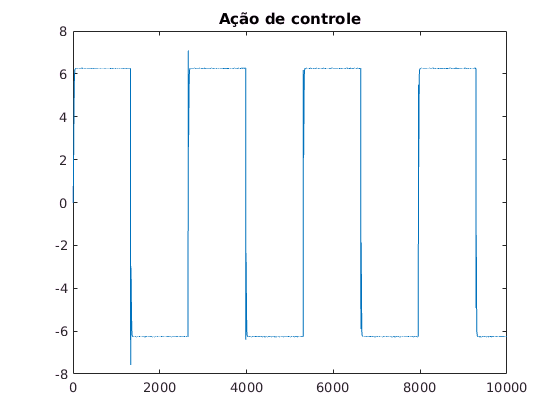

%%mr2
clear
nit = 10000;
h = 0.0377;
for t = 1:nit
    %onda quadrada de período 100 segundo
    u1 = sin(2*pi*(1/100)*t*h);
    if u1 >= 0
       w(t) = 1;
    else
       w(t) = -1;
    end
    % sinal aleatório de amplitude entre -1 e 1
    if rand > 0.5
       u(t)= 1;
    else
       u(t)= -1;
    end
     e= u*0.001; %  ruido de amplitude entre -0.001 e 0.001
     w=w+e;
    Ao=0.9048; Bo = 0.3045; gama = 0.75;  am = 0.8282; bm = 0.1718;
    if t<3
        ym(t)=0;  g(t)=0; f(t)=0; ymf(t)=0;  erropm(t)=0; ucon(t)=0; w(t)=0;
    else
        ym(t) = am*ym(t-1) + bm*w(t-1);%modelo
        ymf(t) = -Ao*ymf(t-1) + Bo*ucon(t-1); %planta  real em malha fechada
        erropm(t) = ymf(t) - ym(t);% sinal de erro entre a panta e o modelo
        g(t) = g(t-1)*(1-am) + am*g(t-2) - gama*w(t-2)*erropm(t-1);
        f(t) = f(t-1)*(1-am) + am*f(t-2) + gama*ymf(t-2)*erropm(t-1);
        ucon(t) = -f(t)*ymf(t) + g(t)*w(t); %AÇÃO DE CONTROLE
    end
end
t = 1:nit;
%gms=tf(11.4144,[1 4.1271]); gmz=c2d(gms,h,'zoh'); ymodelo = lsim(gmz,w,t);
plot(t,ucon);title('Ação de controle'),xlabel('amostragem');grid;

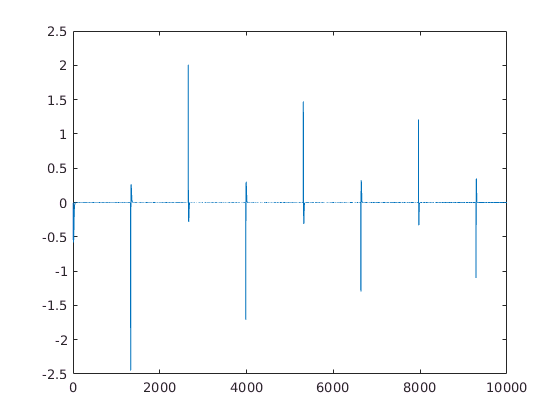

plot(t,erropm);title('resposta do modelo e em malha fechada'),xlabel('amostragem');grid;

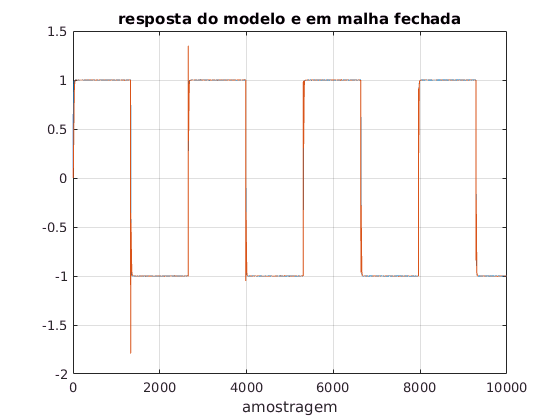

plot(t,ym,t,ymf);title('resposta do modelo e em malha fechada'),xlabel('amostragem');grid;